# Boundary Work

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

Work is computed as force times distance, but unit analysis shows that work can be expressed in other ways. This script will investigate pressure-volume (PV) diagrams and their relationship to work in a closed system.

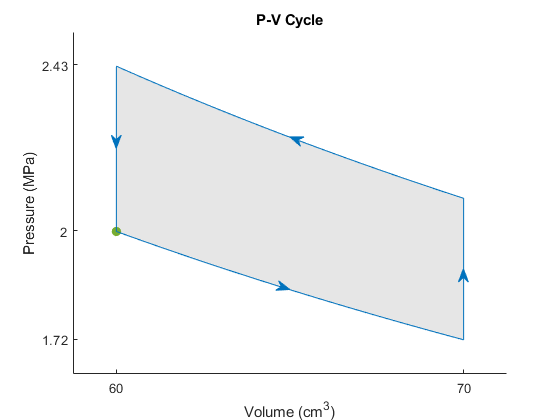

Different process paths on a pressure-volume plot express different amounts of work.

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane. Several specialized helper functions for creating pressure-volume plots can be found in the FunctionLibrary folder.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if they are run out of order.

## Using a P-V diagram to compute work

The work required to change a system from one state to another depends on the specific *path* in P-V space traveled. This means work is *path dependent.* To track the fact that the path matters, we use a different symbol, $\delta$, for an inexact differential. 


$$\text{Work} = \text{Force} * \text{Distance}$$


Incrementally, this means that for a quasi-equilibrium process,


$$\delta (\text{Work}) = \text{Force} \cdot ds$$


                                                    
$$= (\text{Pressure}*\text{Area})\cdot ds$$
                   

                                
$$=\text{Pressure} \cdot dV$$
            

Recall that pressure is a state variable that is a function of two other state variables: volume and temperature. Given sufficient data, this allows us to identify the path a system takes by writing the pressure as a function of volume which allows us to compute the desired integral. 


$$\text{Work} = \int_{\text{start}}^{\text{finish}}P(V)\; dV$$


In mathematics, this is called "parametrizing the curve."

###  Sign Conventions

Whether work is done **by** a system or **on** a system is a distinction recognized in all approaches to thermodynamics. Which of these counts as positive work varies based on discipline, however. In physics, to create agreement between mechanics and thermodynamics, work done by a system is assigned a negative value. In engineering, work done by a system is generally the goal and is assigned a positive value.  We will follow the engineering convention.

### Energy Consequences

When the work done by a system is positive, this means that energy is being transferred from the system to the environment. When the work done by a system is negative, this means that energy is being transferred into the system from the environment.

#### Consider a box and its potential energy

As you have likely seen in physics, let's consider a box of rocks as our system. If you lift the box from the ground to a table, the box increases its potential energy. Because energy was added to the system, this is negative work done by the box. Now, if you slide the box across the table, the potential energy of the system is unchanged. This is an example of zero work. Finally, if you push the box off the edge of the table, it will drop to the ground, and energy is extracted from the system as it crashes to the floor. In this case, the box has done positive work. 

## **Piston-Cylinder Example**

Consider a frictionless piston-cylinder device containing 0.8 cubic meters of air at 110 kPa and 75C. Compute the work done by the system in each of the following scenarios.

### **Isobaric**

a) The volume expands isobarically to 1.2 cubic meters. 

Assumption: The expansion occurs in quasi-equilibrium.

 
pvPlot([0.8 1.2],"m^3",[110 110],"kPa",showArea=true,Title="P-V plot with constant pressure");

workDone = "positive";
qualitativeWorkCheck(workDone,"1a")

The work done by the piston-cylinder system is, mathematically:


$$W = \int_{0.8}^{1.2} 110\; dV$$


In MATLAB, this can be expressed as:

% Create a symbolic variable V
syms V
% 
W = int(110,V,0.8,1.2);
disp("W = " + double(W) + " kJ")

  **Pro-tip**. The [`double`](https://www.mathworks.com/help/symbolic/double.html)`(W)` command converts between [data types](https://www.mathworks.com/help/matlab/data-types.html). You could learn more about data types in the courseware modules [Fundamentals of Programming](https://www.mathworks.com/matlabcentral/fileexchange/103225-fundamentals-of-programming) and [Programming: Organizing Data](https://www.mathworks.com/matlabcentral/fileexchange/115900-programming-organizing-data). Data types are also covered in self-paced online courses, including [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), [MATLAB Fundamentals](https://matlabacademy.mathworks.com/details/matlab-fundamentals/mlbe#module=11), and [MATLAB Programming Techniques](https://matlabacademy.mathworks.com/details/matlab-programming-techniques/mlpr#module=2).

class(W)
class(double(W))

Because 

displayFormula("'Work ' = int(110,V,0.8,1.2)")

### **Isochoric**

b) The system is cooled to 60C isochorically.

Assumption 1: The system is in quasi-equilibrium.

 
pvPlot([0.8 0.8],"m^3",[110 110*(60/75)],"kPa",showArea=false,Title="P-V plot with constant volume");

workDone = "zero";
qualitativeWorkCheck(workDone,"1b")

This is correct.


The work done by the piston-cylinder system is


$$\text{Work} = \int_{0.8}^{0.8}P\; dV = 0 \text{ kJ}$$


### **Isothermal**

c) The piston compresses the air in the cylinder isothermally until it reaches a volume of 0.5 cubic meters.

Assumption 1: The expansion occurs in quasi-equilibrium.

Assumption 2: Air can be treated as an ideal gas at these temperatures and pressures.


$$PV = nR_uT$$


By Assumption 1 and Assumption 2, we know that 

$PV = P_0V_0 = (0.8)\cdot(110) \text{ kJ} = 88 \text{ kJ}$.

Therefore, we can use the relationship $P = \frac{88}{V}$ to compute pressure values in $\text{kPa}$ at known volumes.

 
vValues = 0.8:-0.01:0.5;
pValues = 88./vValues;
pvPlot(vValues,"m^3",pValues,"kPa",showArea=true,Title="P-V plot of an ideal gas");

Is the work done by this system positive, negative, or zero?

workDone = "negative";
qualitativeWorkCheck(workDone,"1c")

This is correct.


The work done by the piston-cylinder system is

$\displaystyle \text{Work} = \int_{0.8}^{0.5}\frac{88}{V}\; dV$.

 
% Symbolically calculate the integral in kJ
syms V
W = int(88/V,V,0.8,0.5)
% Convert the solution to a decimal value in kJ
Work = double(W)
% Create and display a string including the output value.
str = "There is approximately " + Work + " kJ of work" ... 
    + " done by the piston-cylinder system in this scenario.";
disp(str)

### **Reflect**.

- Can you compute the work done by a piston-cylinder system knowing only its change in pressure? If so, how?

- Can you compute the work done by a piston-cylinder system knowing only its change in volume? If so, how?

- Can you sketch a P-V plot with a cycle that generates positive work? 

## ** Exercise 1. Compute work in a piston-cylinder system**

Consider a frictionless, sealed piston-cylinder device containing 30 ccs of steam at 200 kPa and 150C. Use the provided data to compute the work done by a four-step cycle:

- Compress the steam to 20 ccs at constant pressure by changing the temperature.

- Fix the volume in the cylinder by keeping the piston in place and increase the temperature back to 150C.

- Unlock the piston and allow it to expand at constant pressure to 30 ccs as the temperature changes.

- Fix the volume in the cylinder by keeping the piston in place and decrease the temperature to lower the pressure to 200 kPa.

The mass density in $\text{kg}/\text{m}^3$ is collected in the table `dMassTable`, where the data is extracted from CoolProp. [4] Each row is a constant temperature and each column is a constant pressure, as labeled. 

 
load waterData.mat dMassTable PValTable
dMassTable

The pressure (in kPa) is collected in `PValTable`. Each row is a constant temperature and each column is a constant mass density in $\text{kg}/\text{m}^3$.

PValTable

  **Pro-tip**. You can extract data from a table into a table using parentheses or extract the values using curly braces.

a) What is the mass density in $\text{kg}/\text{m}^3$ at 200 kPa and 150C?

dMassStart = dMassTable{"150C","200kPa"}  % as a 1x1 double

b) What is the mass density in $\text{kg}/\text{m}^3$ after compressing to 20 ccs in Step 1?

Hint: Remember that $\text{mass} = \text{(mass density)} \times \text{volume}$.

dMassCompressed = dMassStart*3/2  % as a 1x1 double

c) What is the pressure of the steam in kPa after raising the temperature in Step 2?

newPressure = PValTable{"150C","1.5627"}  % as a 1x1 double
 
checkCycleParams(dMassStart,dMassCompressed,newPressure);

d) Using the values you determined in Parts a)-c), draw the P-V cycle diagram and compute the work done by this system. 

Remember that the cycle is as follows:

- Compress the steam to 20 ccs at constant pressure by changing the temperature.

- Fix the volume in the cylinder by keeping the piston in place and increase the temperature back to 150C.

- Unlock the piston and allow it to expand at constant pressure to 30 ccs as the temperature changes.

- Fix the volume in the cylinder by keeping the piston in place and decrease the temperature to lower the pressure to 200 kPa.

% Using the results of parts a)-c),
% determine the paths and draw the P-V diagram

% Compute the work done by this cycle 


% % Solution 

**Solution to Exercise 1**

Part d)

% Draw the P-V diagram
pvPlotCycle("cm^3","kPa",[30 20],[200 200],...
    [20 20],[200 newPressure],...
    [20 30],[newPressure newPressure],...
    [30 30],[newPressure 200]);

The work done by this cycle is:


$$\text{Work} = \int_{30}^{20}200\; dV + \int_{20}^{20}P\; dV + \int_{20}^{30} 297.315\; dV + \int_{30}^{30}P\; dV$$


            = (small and negative) + (zero) + (large and positive) + (zero)

= positive work                                                              

% Compute value of the work 
syms P V
W = double(int(200,V,30,20) + int(P,V,20,20) + int(newPressure,V,20,30) + int(P,V,30,30));
str = "The work done by this cycle is approximately " + W + " kPa-cm^3 or " + W*1000/(100^3) + " J.";
disp(str)
% % End Solution

### Reflection: Plotting the Density of Water

In the density table, you should have noticed a discontinuous jump in the data. What happens to water at a fixed pressure as you increase the temperature? Does that explain why the density jumps? 

% Identify the variables to plot
load waterData.mat dMassTable
tValues = 100:10:600;   % Temperatures in C
pValues = 1:0.5:6;      % Pressures in kPa

% Create a surface plot
[X,Y] = meshgrid(pValues,tValues);
surf(X,Y,dMassTable{1:numel(tValues),1:numel(pValues)})
view([-116 15])

% Add labels
title("A State Change: Liquid to Gas")
xlabel("Pressure (kPa)")
ylabel("Temperature (C)")
zlabel("Density (kg/m^3)")

We could plot a full state diagram for water as well:

load waterData.mat Ttr Ptr Tc Pc Tsat Psat Tsub Psub Tmelting Pmelting

figure

% Create the semilog scale plot
scatter(Ttr, Ptr,"filled")     % Plot the triple point
set(gca, 'yscale', 'log')

% Set axis labels and limits
xlabel("T (K)")
ylabel("P (Pa)")
xlim([50 650])
ylim([0.01 2e9])
title("State Diagram for Water")

hold on
scatter(Tc, Pc,"filled")       % Plot the critical point
semilogy(Tsat, Psat)           % Plot the saturation curve
semilogy(Tmelting, Pmelting)   % Plot the melting curve
plot(Tsub, Psub)               % Plot the sublimation curve
patch([383.15 383.15 423.15 423.15 383.15],[200 300 300 200 200],[0.9 0.9 0.9])
hold off

% Add labels to each region
text(100,10^5,"Solid")
text(300,10^7,"Liquid")
text(400,10,"Gas")

% Add a legend identifying the points
legend(["Triple Point","Critical Point","","","","Region in Exercise 1"],"Location","best")

## ** Exercise 2. Apply the van der Waals equation of state**

The first correction to the ideal gas law was described in 1873 by Johannes Diderik van der Waals when he developed an equation of state based on molecular attraction that worked for higher pressures than the ideal gas law [1]. The van der Waals equation of state is:

$\left[P+a\left(\frac{1}{V_m}\right)^2\right]\left(V_m-b\right) = R_uT$, 

where $V_m$ is the molar volume $\frac{V}{n}$ with $n$ moles occupying a volume $V$, and $a$ and $b$ are characteristics of the individual gas, 

$a = 3P_cV_c^2 = \frac{27(R_uT_c)^2}{64P_c}$,      and      $b = \frac{V_c}{3}=\frac{R_uT_c}{8P_c}$,

 where $P_c$ is the critical pressure, $V_c$ is the molar volume at the critical point, and $T_c$ is the critical temperature. 

Calculate the work done by a piston-cylinder system containing steam. For steam we have,

$T_c = 647.0960 ~\text{K}$,    $P_c = 22064~\text{kPa}$,    and    $R_u = 8.3144~ \text{J/mol/K}$

a) Calculate the value $a$ and $b$ for steam to four significant digits.

load waterData.mat Tc Pc Ru 
% % Solution
a = 27*(Ru*Tc)^2/(64*Pc)
b = (Ru*Tc)/(8*Pc)
% % End Solution
 
checkVDWParams(a,b);


b) Consider a system where you are working with a volume of 60 ccs of steam at 450C and 2MPa. How well does the ideal gas law model this system? How well does the van der Waal equation of state model this system?

The table `dMolarTable` contains the molar density of water in $\text{mol}/\text{m}^3$ at the specified pressures and temperatures.

load waterData.mat dMolarTable
dMolarTable
% % Solution

**Solution to Exercise 2 b)**

myP = 2e6;                        % pressure in Pa
myT = 450+273.15;                 % temperature in K
dM = dMolarTable{"450C","2MPa"};  % molar density of water at 450C and 2MPa
Vm = 1/dM;                        % V/n in m^3/mol
% Does ideal gas law work? i.e. P*Vm == Ru*T?   
myP*Vm             % P*Vm
Ru*myT             % Ru*T

% Does vdW work? i.e., (P+a*(1/Vm)^2)*(Vm-b) == Ru*T?
(myP + a*(dM)^2)*(Vm-b)  % (P+a*(1/Vm)^2)*(Vm-b)
Ru*myT                   % Ru*T
% % End Solution

c) Using the van der Waal equation of state, calculate how much work is done by the system if you expand the volume to 70 cc isothermally, then isochorically raise the temperature to 600C, then isothermally decrease the volume to 60 cc at constant temperature, and finally isochorically return the temperature to 450C. 

% % Once you determine the four paths, you can 
% % plot them using pvPlotCycle, e.g., 

% % Solution

**Solution to Exercise 2 c)**

syms P(V,T)
V0 = 60;
myT = 450+273.15;
P(V,T) = (Ru*T)./(V*Vm/V0-b)-a*(V0/(V*Vm))^2;
digits(6)
Rudec = vpa(double(Ru));
ndec = vpa(double(V0/Vm));
bdec = vpa(double(b));
adec = vpa(double(a));
displayFormula("P(V,T) = (Rudec*T)./(V/ndec-bdec)-adec*(ndec/V)^2")
% Path 1
V1 = 60:0.1:70;
P1 = double(P(V1,myT));
% Path 2
newT = 600+273.15;
V2 = ones(size(V1))*70;
T2 = linspace(myT,newT,numel(V2));
P2 = double(P(V2,T2));
% Path 3
V3 = fliplr(V1);
P3 = double(P(V3,newT));
% Path 4
V4 = ones(size(V1))*60;
T4 = linspace(newT,myT,numel(V2));
P4 = double(P(V4,T4));

pvPlotCycle("cm^3","MPa",V1,P1*1e-6,V2,P2*1e-6,V3,P3*1e-6,V4,P4*1e-6);

This shows a path which contributes a small amount of positive work, then zero, then a large amount of negative work, then zero. We expect the overall work done by this system to be negative, so it will require energy input from its surroundings to run in this cycle. 

myTnum = vpa(double(myT));
newTnum = vpa(double(newT));
V2num = vpa(double(V2(1)));
V4num = vpa(double(V4(1)));
displayFormula("'Work ' = int(P(V,myTnum),V,60,70) + int(P(V2num,T),V,70,70) " + ...
    "+ int(P(V,newTnum),V,70,60) + int(P(V4num,T),V,60,60)")
digits(4)
P1form = vpa(subs(P,T,myTnum));
P2form = vpa(subs(P,V,V2num));
P3form = vpa(subs(P,T,newTnum));
P4form = vpa(subs(P,V,V4num));
displayFormula("'Work ' = int(P1form,V,60,70) + int(P2form,V,70,70) + " + ...
    "int(P3form,V,70,60) + int(P4form,V,60,60)")
digits(32)
W = double(vpa(int(P(V,myTnum),V,60,70) + int(P(V,newTnum),V,70,60)));
str = "The work done by this cycle is approximately " + W*1e-6 + " MPa-cm^3 or " + W/(100^3) + " J.";
disp(str)
% % End Solution

## ** Exercise 3. Apply the Peng-Robinson equation of state**

The Peng-Robinson equation of state is


$$P = \frac{RT}{V_m-b}-\frac{a\alpha}{V_m^2+2bV_m-b^2}$$
 

where 

$a = \frac{0.45724R_u^2T_c^2}{P_c}$,       $b = \frac{0.07780R_uT_c}{P_c}$,  

and 


$$\alpha = \left(1+\left(0.37464 + 1.54226\omega - 0.26992\omega^2\right)\left(1-\sqrt{\frac{T}{T_c}}\right)\right)^2$$


where $R_u$ is the ideal gas constant, $T_c$ is the critical temperature, $P_c$ is the critical pressure, $V_m$ is the molar volume, and $\omega$ is the acentric factor of species [3].

Repeat Exercise 2, but use the Peng-Robinson equation of state instead of van der Waals. What is the same, and what is different?

a) Calculate the value of the parameters $a$, $b$, and $\alpha$ for steam at 450C to four significant digits. The critical temperature, critical pressure, gas constant, and acentric factor for water are available in `waterData.mat`.

load waterData.mat Tc Pc Ru omega

aPR = 0.45724*(Ru*Tc)^2/Pc;
bPR = (0.07780*Ru*Tc)/Pc;
syms alphaPR(T)
alphaPR(T) = (1+(0.37464+1.54226*omega-0.26992*omega^2)*(1-sqrt(T/Tc)))^2;
alphaPRat450 = double(vpa(alphaPR(723.15)));
str = "In the Peng-Robinson equation for water: " + newline + ...
    "The value of a is " + aPR + "." + newline + "The value of b is " + bPR + "." + newline ...
    + "The value of alpha at T = 450C is " + alphaPRat450 + ".";
disp(str)
 

checkPRParams(aPR,bPR,alphaPRat450);

**Warning: Parameter names are re-used in different equations**

Notice that there are parameters $a$ and $b$ in both the van der Waals and the Peng-Robinson equations of state. You might name the first set `avW` and `bvW` and the second set `aPR` and `bPR`. Then you could compare the values. How close are they?

aVW = a;
bVW = b;
aVW-aPR
(aVW-aPR)/aVW
bVW-bPR

Note that the difference between `aVW` and `aPR` is only 8% of `aVW` while the difference between `bVW` and `bPR` is 37% of `bVW` although the absolute difference between `aVW` and `aPR` is larger by 3 orders of magnitude. All of these numbers are small, though.

b) Consider a system where you are working with a volume of 60 ccs of steam at 450C and 2MPa. How well does the ideal gas law model this system? How well does the Peng-Robinson equation of state model this system? What about steam at 600C and 2MPa? A molar density table for water in mol/m$^3$ is available in `waterData.mat`.

load waterData.mat dMolarTable
dMolarTable
% % Solution

**Solution to Exercise 3 b)**

% my pressure in Pa
myP = 2e6;
% my temperature in K
myT = 450+273.15;      % 450C
myT600 = 600+273.15;   % 600C

% % Identify the mass density in mol/m^3
dM = dMolarTable{"450C","2MPa"};
dM600 = dMolarTable{"600C","2MPa"};
Vm = 1/dM;
Vm600 = 1/dM600;

% Does the ideal gas law work?
idealGasPressure = (Ru*myT)*dM;
idealGasPressure600 = (Ru*(myT600))*dM600;
disp("The ideal gas law estimates the pressure to be " + idealGasPressure/1e6 + " MPa at 450C, " + newline + ...
"and " + idealGasPressure600/1e6 + " MPa at 600C, while the actual pressure is " + myP/1e6 + " MPa.")

% Does PR work?
PR450 = (Ru*myT)/(Vm-bPR) - (aPR*double(vpa(alphaPR(myT))))/(Vm^2 + 2*bPR*Vm-bPR^2);
PR600 = (Ru*myT600)/(Vm600-bPR) - (aPR*double(vpa(alphaPR(myT600))))/(Vm600^2 + 2*bPR*Vm600-bPR^2);
disp("The Peng Robinson law estimates the pressure to be " + PR450/1e6 + " MPa at 450C, " + newline + ...
    "and " + PR600/1e6 + " MPa at 600C, while the actual pressure is " + myP/1e6 + " MPa.")

While the Peng-Robinson law consistently underestimates the pressure here, it is always closer to the actual value at both 450C and at 600C. 

% % End Solution

c) Using the Peng-Robinson equation of state, calculate how much work is done by the system if you expand the volume to 70 cc isothermally, then isochorically raise the temperature to 600C, then isothermally decrease the volume to 60 cc at a constant temperature, and finally isochorically return the temperature to 450C. 

load waterData.mat dMolarTable
dMolarTable
% % Solution

**Solution to Exercise 3 c)**

load waterData.mat dMolarTable
syms P(V,T) 
V0 = 60;

% % Identify the mass density in mol/m^3
dM = dMolarTable{"450C","2MPa"};
Vm = 1/dM;

myT = 450+273.15;
alphaT = vpa(subs(alphaPR,T));
P(V,T) = (Ru*T)./(V*Vm/V0-bPR)-(aPR*alphaPR(T))/(((V*Vm)/V0)^2+2*bPR*(V*Vm/V0)-bPR^2);
digits(6)
Rudec = vpa(double(Ru));
ndec = vpa(double(V0/Vm));
bdec = vpa(double(bPR));
adec = vpa(double(aPR));
displayFormula("P(V,T) = (Rudec*T)./(V/ndec-bdec)-(adec*alphaT)/((V/ndec)^2+2*bdec*V/ndec-bdec^2)")

% Path 1
V1 = 60:0.1:70;
P1 = double(P(V1,myT));
% Path 2
newT = 600+273.15;
V2 = ones(size(V1))*70;
T2 = linspace(myT,newT,numel(V2));
P2 = double(P(V2,T2));
% Path 3
V3 = fliplr(V1);
P3 = double(P(V3,newT));
% Path 4
V4 = ones(size(V1))*60;
T4 = linspace(newT,myT,numel(V2));
P4 = double(P(V4,T4));

pvPlotCycle("cm^3","MPa",V1,P1*1e-6,V2,P2*1e-6,V3,P3*1e-6,V4,P4*1e-6);
myTnum = vpa(double(myT));
newTnum = vpa(double(newT));
V2num = vpa(double(V2(1)));
V4num = vpa(double(V4(1)));
displayFormula("Work = int(P(V,myTnum),V,60,70) + int(P(V2num,T),V,70,70) + int(P(V,newTnum),V,70,60) + int(P(V4num,T),V,60,60)")
W = double(vpa(int(P(V,myTnum),V,60,70) + int(P(V,newTnum),V,70,60)));
str = "The work done by this cycle is approximately " + W*1e-6 + " MPa-cm^3 or " + W/(100^3) + " J.";
disp(str)
digits(32)
% % End solution

### Why are there multiple equations of state?

Different equations of state apply in different regimes. All of the equations of state discussed in this script are intended to work for gases. As the pressure approaches the critical pressure, $P_c \approx 22.064$MPa, observe how the different equations of state approximate the values in the table. 

Ideal Gas law: 1834           

Van der Waals equation: 1873                            

Peng-Robinson equation: 1976                              

Table: 2012

myPressure = 20;
plotPressureLines(myPressure)

## **Application: Extracting mechanical work from a piston**

The Simulink model [`Work_demo`](matlab: open("Work_demo.slx")) consists of an adiabatic piston-cylinder system. 

open("Work_demo")

If you haven't done so yet, you can use the command 

out = sim("Work_demo");

to simulate this piston-cylinder system. 

Extract the pressure and volume data from the simulation into `pressureData` and `volumeData` variables with the desired units.

pressureData = out.pressure.Data(:)./1e3;    % kPa
volumeData = out.volume.Data(:)*1e6;         % cm^3
timeData = out.pressure.Time;                % s

Create a plot similar to the scope results in the Simulink model by plotting the pressure and volume as functions of time.

tL = tiledlayout(2,1);
nexttile
plot(timeData,pressureData)
xlabel("Time (s)")
ylabel("Pressure (kPa)")
nexttile
plot(timeData,volumeData)
xlabel("Time (s)")
ylabel("Volume (cm^3)")

  **Try**. Plot all three variables together. Then click the figure and use the Rotate 3D plotting tool  in the toolbar to rotate the plot in different directions. Try looking at a Time-Pressure plot, a Time-Volume plot, and a Pressure-Volume plot. 

figure
p1 = plot3(timeData,volumeData,pressureData);
p1.DataTipTemplate.DataTipRows = [dataTipTextRow("Time",timeData);...
    dataTipTextRow("Volume",volumeData);...
    dataTipTextRow("Pressure",pressureData)];
hold on
p = scatter3(timeData(1),volumeData(1),pressureData(1),"o","filled","SeriesIndex",2);
title("Pressure-Volume-Time plot")
hold off
xlabel("Time (s)")
ylabel("Volume (cm^3)")
zlabel("Pressure (kPa)")
maxIdx = numel(timeData);
animation = "P-V";
if animation == "P-V"
    view([90.0 0])
    title("Projected along the Time axis")
elseif animation == "T-P"
    view([0 90.0])
    title("Projected along the Volume axis")
elseif animation == "T-V"
    view([180 90.0])
    title("Projected along the Pressure axis")
end
for k = 1:2:maxIdx
    p.XData = timeData(k);
    p.YData = volumeData(k);
    p.ZData = pressureData(k);
    p.Parent.Subtitle.String = "P = " + round(pressureData(k),1) + " kPa, "+ ...
        "V = " + round(volumeData(k),1) + " cm^3, t = "+ round(timeData(k),2) + " s";
    drawnow
end

**Reflect.**

- Is this system performing positive work, negative work, or zero work? Why?

- How would you test your answer?

  **Try**. Select different values for the `stopIdx` value and compute how much work has been done by the system. You can visualize the work done by selecting the checkbox `ShowArea`. Remember the color indicates the sign of the area. Do you see different colors here? Why or why not? 

stopIdx = 71;
pvPlot(volumeData,"cm^3",pressureData,"kPa");

hold on
pvPlot(volumeData(1:stopIdx),"cm^3",pressureData(1:stopIdx),"kPa",ShowArea=true);
hold off;
work = trapz(volumeData(1:stopIdx),pressureData(1:stopIdx))/1e6;
disp("The work after " + string(out.pressure.Time(stopIdx)) + " seconds is " + work + "kJ")

Create a plot of the work done as a function of time:

plot(out.pressure.Time,cumtrapz(volumeData,pressureData))
xlabel("Time (s)")
ylabel("Work (kJ)")

## Further Exploration

  **Try**. Open the [`Work_demo`](matlab: edit Work_demo.slx) Simulink model and explore. Try opening up some of the blocks by double-clicking and looking at their property values. Can you figure out how to investigate any of the following?

- What happens if you use an isothermal system rather than an adiabatic system?

- What happens if you change the dimensions of your piston? 

- What happens if you change the characteristics of your gas?

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## **Definitions**

  **Exact vs. Inexact Functions**

An exact function is a state function. In this case, the integral from one state to another is simply the difference in the values of the underlying ("antiderivative") function at each state. The fundamental theorem of calculus that you learned in your first calculus course is a statement about an exact function $f(x)$ which has an antiderivative $F(x)$:


$$\int_a^b f(x)\; dx = F(b)-F(a)$$


An inexact function is a path function. If we write $\displaystyle \int_a^b f(x)\delta x,$ there is no antiderivative function $F(x)$. The integral from state $a$ to state $b$ depends on the choice of the path taken from $a$ to $b$. In mathematics, the integral of an inexact function is called a line integral. 

Return to text

  **Quasi-equilibrium**

A system is in quasi-equilibrium if the process changes happen much more slowly than the rate at which thermodynamic equilibrium is re-established in a new state. In this case, the system can be considered consistently in thermodynamic equilibrium at each point for purposes of calculus as smooth infinitesimal change. This idealized simplification is practical for computation and can be thought of as constant-voltage batteries, zero-resistance wires, or frictionless pulleys.

Return to text

  **Isothermal: **constant temperature

This contrasts with **adiabatic**. An adiabatic process is isolated from the environment so no heat is added or removed from the system. An isothermal process is embedded in its environment such that whatever heat flow is required to keep a constant temperature in the system occurs. 

Return to text

  **Isobaric:** constant pressure

Return to text

  **Isochoric: **constant volume

This is also called isovolumetric. 

Return to text

  **Adiabatic: **thermally isolated, no heat flow

This is the result when the boundary of your system is a perfect thermal insulator. This contrasts with **isothermal**, when the boundary of your system is perfectly porous to heat such that a constant temperature is maintained.

Return to text

## Citations

[1] Johannes Diderik van der Waals – Facts. NobelPrize.org. Nobel Prize Outreach AB 2022. Wed. 2 Nov 2022. [https://www.nobelprize.org/prizes/physics/1910/waals/facts/](https://www.nobelprize.org/prizes/physics/1910/waals/facts/) 

[2] Coleman, Larry. (Apr. 21, 2021). *Equation of State.* LibreTexts Engineering. Thur. 8 Dec 2022. [https://eng.libretexts.org/Bookshelves/Chemical_Engineering/Distillation_Science_(Coleman)/05%3A_Equation_of_State](https://eng.libretexts.org/Bookshelves/Chemical_Engineering/Distillation_Science_(Coleman)/05%3A_Equation_of_State)

[3] Methane Gas Volume Expansion Ratios and Ideal Gas Deviation Factors for the Deep-Water Bering Sea Basins. pubs.usgs.gov. USGS: Science for a Changing World. Fri. 4 Nov 2022. [https://pubs.usgs.gov/of/2005/1451/equation.html#:~:text=The%20Peng%2DRobinson%20equation%20of,factor%20of%20each%20species%20involved.](https://pubs.usgs.gov/of/2005/1451/equation.html#:~:text=The%20Peng%2DRobinson%20equation%20of,factor%20of%20each%20species%20involved.)

[4] Bell, I. H., Wronski, J., Quoilin, S., & Lemort, V. (2013). Pure and Pseudo-pure Fluid Thermophysical Property Evaluation and the Open-Source Thermophysical Property Library CoolProp. *Industrial & Engineering Chemistry Research*, *53*(6), 2498-2508. [https://doi.org/10.1021/ie4033999](https://doi.org/10.1021/ie4033999)

## Local Helper Functions

To see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function plotPressureLines(myPressure)
load waterData.mat aPR bPR alphaPR Ru dM a b CalcTemps

myDm = [50:50:1000 2000:1000:55000];

syms P(Vm,T) Vm T 

% Van der Waals
TvW = (myPressure*1e6+a*myDm.^2).*(1./myDm-b)/Ru;

% Calculate with mass density Vm
P(Vm,T) = (Ru*T)./(Vm-bPR)-(aPR*alphaPR(T))/(Vm^2+2*bPR*Vm-bPR^2);

figure
idx = find(1:0.5:24==myPressure);
plot(CalcTemps(:,idx),myDm./1e3) %#ok<FNDSB>
hold on
plot(myPressure*1e6./myDm/Ru,myDm./1e3)
hold off
ylabel("Molar Density (kmol/m^3)")
xlabel("Temperature (C)")
title("Comparing Tables to Equations of State at " + myPressure + " MPa")
myTpr(Vm) = solve(P(Vm,T)==myPressure*1e6,T);

myTprAll = zeros(size(myDm));
for k = 1:numel(myDm)
    if isreal(double(myTpr(1/myDm(k))))
        myTprAll(k) = min(double(myTpr(1/myDm(k))));
    else
        myTprAll(k) = nan;
        double(myTpr(1/myDm(k)));
    end
end

hold on
plot(TvW,myDm./1e3)
plot(myTprAll,myDm./1e3)
hold off
xlim([0 2000])
legend(["Table" "Ideal Gas" "Van der Waal" "Peng-Robinson"])
end

function tf = checkCycleParams(myStart,myComp,myPres)
load waterData.mat PValTable dMassTable
if ~exist("dMassTable","var") || ~exist("PValTable","var")
    disp("You must load the mass density table and pressure value table" ...
        + newline + "before you can complete this problem.")
    tf = -1;
    return
elseif all([myStart myComp myPres] == 0)
    disp("These are the default values.")
    tf = 0;
else
    if myStart == dMassTable{"150C","200kPa"}
        disp("Your value for the original mass density is correct.")
        tf = 1;
    else
        disp("Your value for the original mass density is incorrect.")
        tf = 0;
    end
    if myComp == (dMassTable{"150C","200kPa"})*2/3
        tf = 0;
        disp("Your value for the compressed mass density is scaled incorrectly.")
        disp("Do you expect the compressed mass density to be larger or smaller?")
    elseif myComp < dMassTable{"150C","200kPa"}
        tf = 0;
        disp("Your value for the compressed mass density is incorrect.")
        disp("Do you expect the compressed mass density to be larger or smaller?")
    elseif myComp ~= (dMassTable{"150C","200kPa"})*3/2
        tf = 0;
        disp("Your value for the compressed mass density is incorrect.")
    else
        disp("Your value for the compressed mass density is correct.")
    end
    try
        myP = PValTable{"150C",string(round(myComp,4))};
        if myPres == myP
            disp("You are using the tables correctly.")
        end
    catch
        if tf == 1
            error("How did you end here?")
        end
    end
    if  myPres ~= PValTable{"150C",string(round((dMassTable{"150C","200kPa"}*3/2),4))}
        disp("You have an incorrect value of the pressure.")
        tf = 0;
    else
        disp("You have a correct value of the pressure.")
    end
end
if tf == 1
    disp("Please finish this problem.")
elseif tf == 0
    disp("Please fix your computations before continuing.")
end
end

function tf = checkVDWParams(myA,myB)
load waterData.mat a b
tola = 5e-5;
tolb = 5e-9;
if abs(myA-a) < tola
    tf = true;
else
    tf = false;
    disp("Your value of a is incorrect.")
end
if abs(myB-b) < tolb
    tf = and(tf,true);
else
    tf = false;
    disp("Your value of b is incorrect.")
end

if tf
    disp("That is correct. Please finish this problem.")
else
    disp("Please fix your computations before continuing.")
end
end

function tf = checkPRParams(myA,myB,myAlpha)
if all([myA == 0 myB == 0 myAlpha == 0])
    str = ["a"; "b"; "alpha"];
    disp("You have not changed the default value for " + str([myA == 0 myB == 0 myAlpha == 0]) + ".")
    return
end
load waterData.mat aPR bPR alphaPR
tola = 5e-5;
tolb = 5e-9;
tolalpha = 5e-5;
if abs(myA-aPR) < tola
    tf = true;
else
    tf = false;
    disp("Your value of a is incorrect.")
end
if abs(myB-bPR) < tolb
    tf = and(tf,true);
else
    tf = false;
    disp("Your value of b is incorrect.")
end
if abs(myAlpha-double(vpa(alphaPR(723.15)))) < tolalpha
    tf = and(tf,true);
else
    tf = false;
    disp("Your value of alpha is incorrect.")
end

if tf
    disp("That is correct. Please finish this problem.")
elseif any([myA == 0 myB == 0 myAlpha == 0])
    str = ["a"; "b"; "alpha"];
    disp("You have not changed the default value for " + str([myA == 0 myB == 0 myAlpha == 0]) + ".")
else
    disp("Please fix your computations before continuing.")
end
end

function qualitativeWorkCheck(myAns,prob)
if myAns == "unanswered"
    disp("This is the default value. Please select positive, negative, or zero.")
elseif prob == "1a" && myAns == "positive"
    disp("This is correct.")
elseif prob == "1b" && myAns == "zero"
    disp("This is correct.")
elseif prob == "1c" && myAns == "negative"
    disp("This is correct.")
else
    disp("This is incorrect. Is the arrow pointing towards positive (increasing)" ...
        + newline + "volumes or negative (decreasing) volumes? Or maybe the volume is constant?")
end
end
% Suppress unused variable warning
%#ok<*NASGU> 